# Two-Body Oscillator

An ideal one-dimensional oscillating system consists of two unit masses, $m_1$ and $m_2$, confined between two walls. Each mass is attached to the nearest wall by a spring of unit elastic constant. Another such spring connects the two masses. Sensors sample $a_1$ and $a_2$, the accelerations of the masses, at $F_s=16$ Hz.

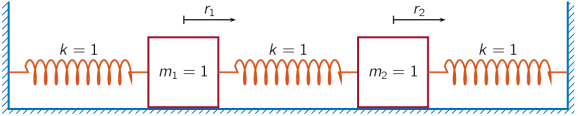

Specify a total measurement time of 16 s. Define the sampling interval $\Delta t=1/F_s$.

Fs = 16;
dt = 1/Fs;
N = 257;
t = dt*(0:N-1);

The system can be described by the state-space model


$$\matrix{x(n+1)=Ax(n)+Bu(n),\cr y(n)=Cx(n)+Du(n),\cr}$$


where $x=\pmatrix{r_1&v_1&r_2&v_2}^T$ is the state vector and $r_i$ and $v_i$ are respectively the location and the velocity of the $i$th mass. The input vector $u=\pmatrix{u_1&u_2}^T$ and the output vector $y=\pmatrix{a_1&a_2}^T$. The state-space matrices are


$$A=\exp(A_c\Delta t),\quad B=A_c^{-1}(A-I)B_c,\quad
C=\pmatrix{-2&0&1&0\cr1&0&-2&0\cr},\quad D=I,$$


the continuous-time state-space matrices are


$$A_c=\pmatrix{0&1&0&0\cr-2&0&1&0\cr0&0&0&1\cr1&0&-2&0\cr},\quad
B_c=\pmatrix{0&0\cr1&0\cr0&0\cr0&1\cr},$$


and $I$ denotes an identity matrix of the appropriate size.

Ac = [0 1 0 0; -2 0 1 0; 0 0 0 1; 1 0 -2 0];
A = expm(Ac*dt);
Bc = [0 0; 1 0; 0 0; 0 1];
B = Ac\(A-eye(4))*Bc;
C = [-2 0 1 0; 1 0 -2 0];
D = eye(2);

The first mass, $m_1$, receives a unit impulse in the positive direction.

ux = [1 zeros(1,N-1)];
u0 = zeros(1,N);
u = [ux;u0];

Use the model to compute the time evolution of the system starting from an all-zero initial state.

x = [0 0 0 0]';
y = zeros(2,N);

for k = 1:N
    y(:,k) = C*x + D*u(:,k);
    x = A*x + B*u(:,k);
end

Plot the accelerations of the two masses as functions of time.

stem(t,y','.')
xlabel('t')
legend('a_1','a_2')
title('Mass 1 Excited')
grid

Convert the system to its transfer function representation. Find the response of the system to a positive unit impulse excitation on the first mass.

[b1,a1] = ss2tf(A,B,C,D,1);
y1u1 = filter(b1(1,:),a1,ux);
y1u2 = filter(b1(2,:),a1,ux);

Plot the result. The transfer function gives the same response as the state-space model.

stem(t,[y1u1;y1u2]','.')
xlabel('t')
legend('a_1','a_2')
title('Mass 1 Excited')
grid

The system is reset to its initial configuration. Now the other mass, $m_2$, receives a unit impulse in the positive direction. Compute the time evolution of the system.

u = [u0;ux];

x = [0;0;0;0];
for k = 1:N
    y(:,k) = C*x + D*u(:,k);
    x = A*x + B*u(:,k);
end

Plot the accelerations. The responses of the individual masses are switched.

stem(t,y','.')
xlabel('t')
legend('a_1','a_2')
title('Mass 2 Excited')
grid

Find the response of the system to a positive unit impulse excitation on the second mass.

[b2,a2] = ss2tf(A,B,C,D,2);
y2u1 = filter(b2(1,:),a2,ux);
y2u2 = filter(b2(2,:),a2,ux);

Plot the result. The transfer function gives the same response as the state-space model.

stem(t,[y2u1;y2u2]','.')
xlabel('t')
legend('a_1','a_2')
title('Mass 2 Excited')
grid

*Copyright 2015 The MathWorks, Inc.*